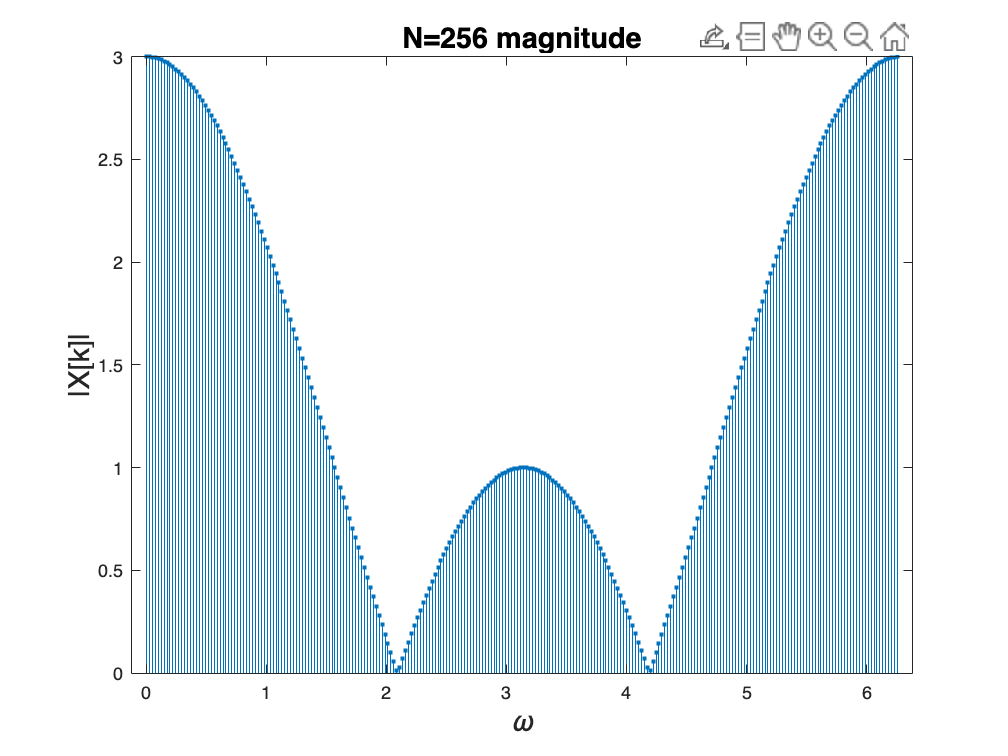

clear;
N = 256;
x_arr = zeros(1,N);

for idx = 1:N
    if idx < 4
        x_arr(idx)=1;
    end
end

x_dtfs = fft(x_arr);

dtfs_freqs = 2*pi*(0:(N-1))/N;

stem(dtfs_freqs, abs(x_dtfs), "filled", '.');
title('N=256 magnitude', 'FontSize', 16);
xlabel('\omega', 'FontSize', 16);
ylabel('|X[k]|', 'FontSize', 16);

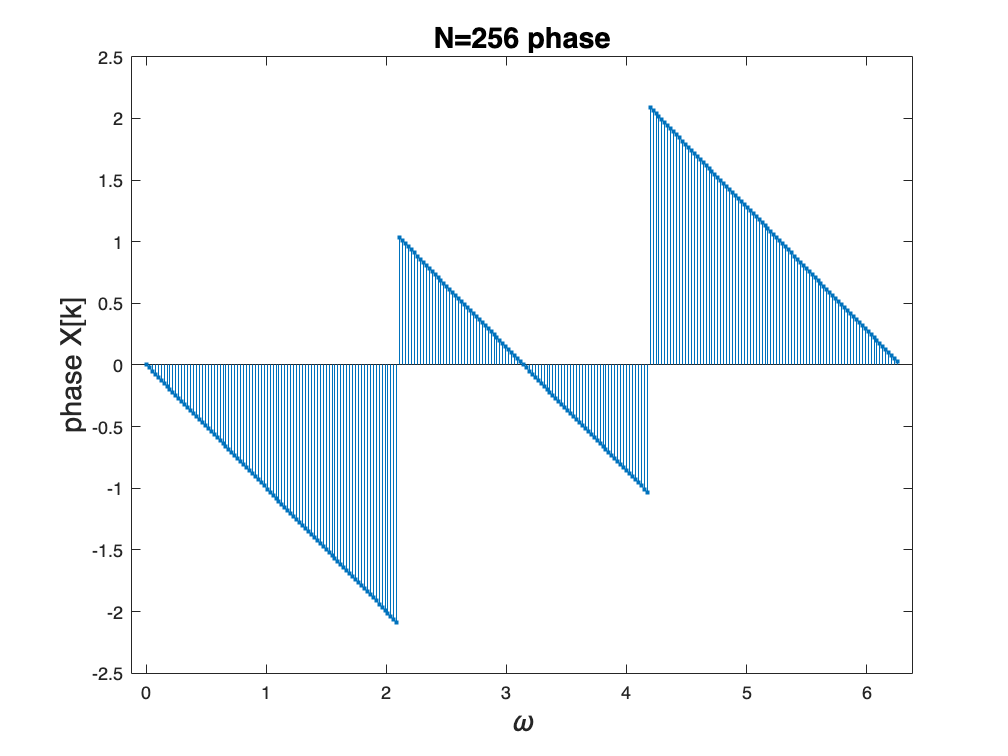


stem(dtfs_freqs, angle(x_dtfs), "filled", '.');
title('N=256 phase', 'FontSize', 16);
xlabel('\omega', 'FontSize', 16);
ylabel('phase X[k]', 'FontSize', 16);